path_time= readtable('path_minitime.csv');

path_dist= readtable('path_minidist.csv');

path_center= readtable('path_center.csv');

path_opt= readtable('path_opt.csv');


track_outer=readtable('bound_outer.csv');

track_inner=readtable('bound_inner.csv');


k_time= readtable('kappa_minitime.csv');

k_dist= readtable('kappa_minidist.csv');

k_center= readtable('kappa_center.csv');

k_opt= readtable('kappa_opt.csv');


s_time= readtable('spline_minitime.csv');

s_dist= readtable('spline_minidist.csv');

s_opt= readtable('spline_opt.csv');

s_center= readtable('spline_center.csv');

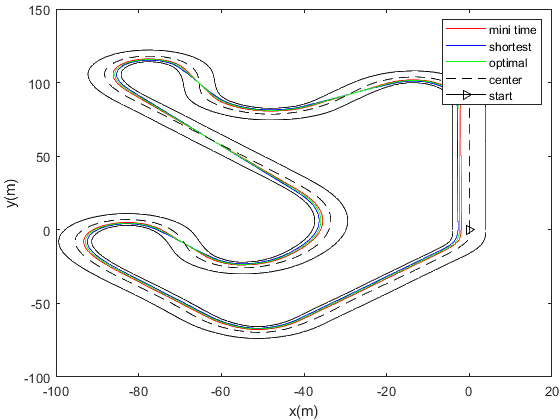

close all;
figure();
plot(path_time.x_Path_x, path_time.path_y, "Color", "red");
hold on;
plot(path_dist.x_Path_x, path_dist.path_y, "Color", "blue");
hold on;
plot(path_opt.x_Path_x, path_opt.path_y, "Color", "green");
hold on;
plot(path_center.x_Path_x, path_center.path_y, "Color", "black", "LineStyle","--");
hold on;
plot(path_center.x_Path_x(1), path_center.path_y(1), "Marker", ">", "Color", "black");
hold on;
plot(track_inner.x_Inner_x, track_inner.inner_y, "Color", "black")
hold on;
plot(track_outer.x_Outer_x, track_outer.outer_y, "Color", "black")
hold off;
legend('mini time', 'shortest', 'optimal', 'center', 'start')
xlabel("x(m)")
ylabel("y(m)")
set(gca,'LooseInset',get(gca,'TightInset'))

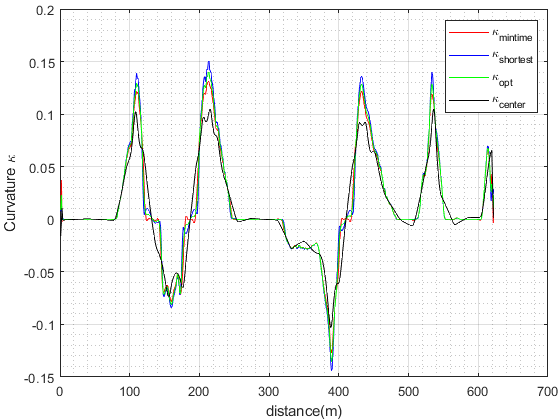

figure();
plot(cumsum(s_center.x_Ds), k_time.x_Kappa(1:end-1), "Color", "red");
hold on;
plot(cumsum(s_center.x_Ds), k_dist.x_Kappa(1:end-1), "Color", "blue");
hold on;
plot(cumsum(s_center.x_Ds), k_opt.x_Kappa(1:end-1), "Color", "green");
hold on;
plot(cumsum(s_center.x_Ds), k_center.x_Kappa, "Color", "black");
hold on; 

hold off;
grid on; grid minor;
legend('\kappa_{mintime}', '\kappa_{shortest}', '\kappa_{opt}', '\kappa_{center}')
xlabel("distance(m)")
ylabel("Curvature \kappa")
set(gca,'LooseInset',get(gca,'TightInset'))